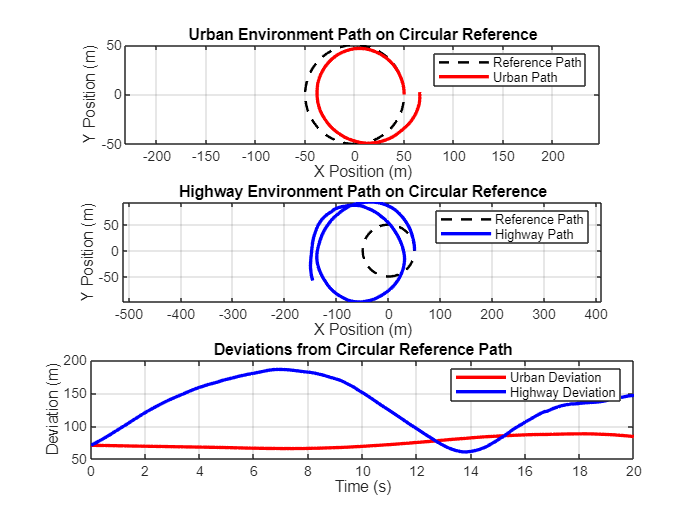

% Kinematic Bicycle Model with Disturbances using ode45
clear all; close all; clc;

% Parameters
l = 2.5; % Distance between front and rear axles (m)
T = 20;  % Total simulation time (s)
dt = 0.1; % Time step
time = 0:dt:T; % Time vector

% Circle Path Parameters
R = 50; % Radius of the circular path (m)
omega_ref = 2 * pi / T; % Angular velocity for the reference path

% Initial Conditions (start at the beginning of the circle)
x0 = R; y0 = 0; theta0 = pi/2; % Starting on the circle at (R, 0), facing upward
initial_conditions = [x0; y0; theta0];

% Simulation Settings for Environments
% Urban Environment
urban_speed = 15; % Low speed (m/s)
urban_steering_angle = deg2rad(3); % Steering angle in radians

% Highway Environment
highway_speed = 45; % High speed (m/s)
highway_steering_angle = deg2rad(1.5); % Smaller steering angle for smoother turns

% Disturbance settings
disturbance_std = 0.02; % Standard deviation for random disturbances

% Reference Path (Circular Path)
x_ref = R * cos(omega_ref * time - pi/2); % X-coordinates for the circle
y_ref = R * sin(omega_ref * time - pi/2); % Y-coordinates for the circle

% Solve the model for urban and highway environments
[t_urban, states_urban] = ode45(@(t, state) kinematic_with_disturbance(t, state, urban_speed, urban_steering_angle, l, disturbance_std), time, initial_conditions);
[t_highway, states_highway] = ode45(@(t, state) kinematic_with_disturbance(t, state, highway_speed, highway_steering_angle, l, disturbance_std), time, initial_conditions);

% Extract states
x_urban = states_urban(:, 1); y_urban = states_urban(:, 2);
x_highway = states_highway(:, 1); y_highway = states_highway(:, 2);

% Calculate deviations from the reference path
urban_deviation = sqrt((x_urban - x_ref').^2 + (y_urban - y_ref').^2);
highway_deviation = sqrt((x_highway - x_ref').^2 + (y_highway - y_ref').^2);

% Plot Results
figure;

% Subplot 1: Urban Environment Path
subplot(3,1,1);
plot(x_ref, y_ref, 'k--', 'LineWidth', 1.5); hold on; % Reference circle
plot(x_urban, y_urban, 'r', 'LineWidth', 2);
xlabel('X Position (m)');
ylabel('Y Position (m)');
title('Urban Environment Path on Circular Reference');
legend('Reference Path', 'Urban Path');
axis equal; grid on;

% Subplot 2: Highway Environment Path
subplot(3,1,2);
plot(x_ref, y_ref, 'k--', 'LineWidth', 1.5); hold on; % Reference circle
plot(x_highway, y_highway, 'b', 'LineWidth', 2);
xlabel('X Position (m)');
ylabel('Y Position (m)');
title('Highway Environment Path on Circular Reference');
legend('Reference Path', 'Highway Path');
axis equal; grid on;

% Subplot 3: Deviations from the Reference Path
subplot(3,1,3);
plot(time, urban_deviation, 'r', 'LineWidth', 2); hold on;
plot(time, highway_deviation, 'b', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Deviation (m)');
title('Deviations from Circular Reference Path');
legend('Urban Deviation', 'Highway Deviation');
grid on;


% Function Definition with Random Disturbance
function dstate = kinematic_with_disturbance(t, state, v, delta, l, disturbance_std)
    % State variables
    x = state(1);
    y = state(2);
    theta = state(3);
    
    % Add random disturbances to steering angle and velocity
    delta_disturbed = delta + disturbance_std * randn; % Disturbance in steering angle
    v_disturbed = v + disturbance_std * randn; % Disturbance in velocity
    
    % Kinematic equations
    x_dot = v_disturbed * cos(theta);
    y_dot = v_disturbed * sin(theta);
    theta_dot = v_disturbed * tan(delta_disturbed) / l;
    
    % Return derivatives
    dstate = [x_dot; y_dot; theta_dot];
end
